# Finned surfaces

## Introduction

The use of finned surfaces to augment the heat transfer rate between solid surfaces and the surrounding fluid is common in several applications, like e.g.:

- Air-cooling of internal combustion engines (i.e. motorcycles).

- Liquid-gas heat exchangers.

- Cooling of electronic components (heat sinks).

The following figure illustrates some examples.

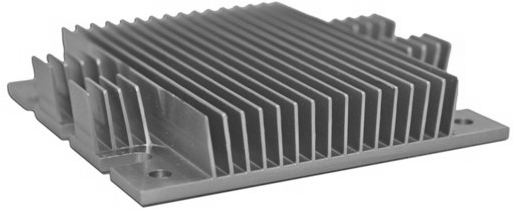   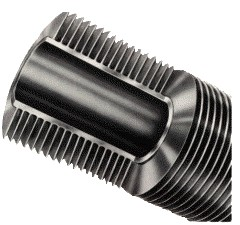

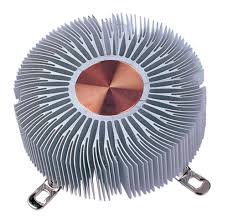                   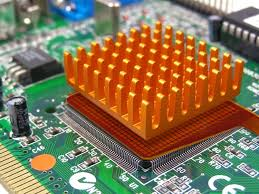

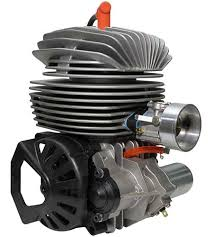           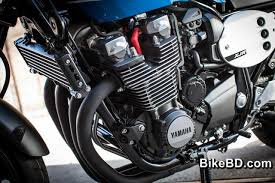

The fins can have several configurations and shapes, and the most simple case is constituted by a plane fin with costant rectangular cross-section, like this:

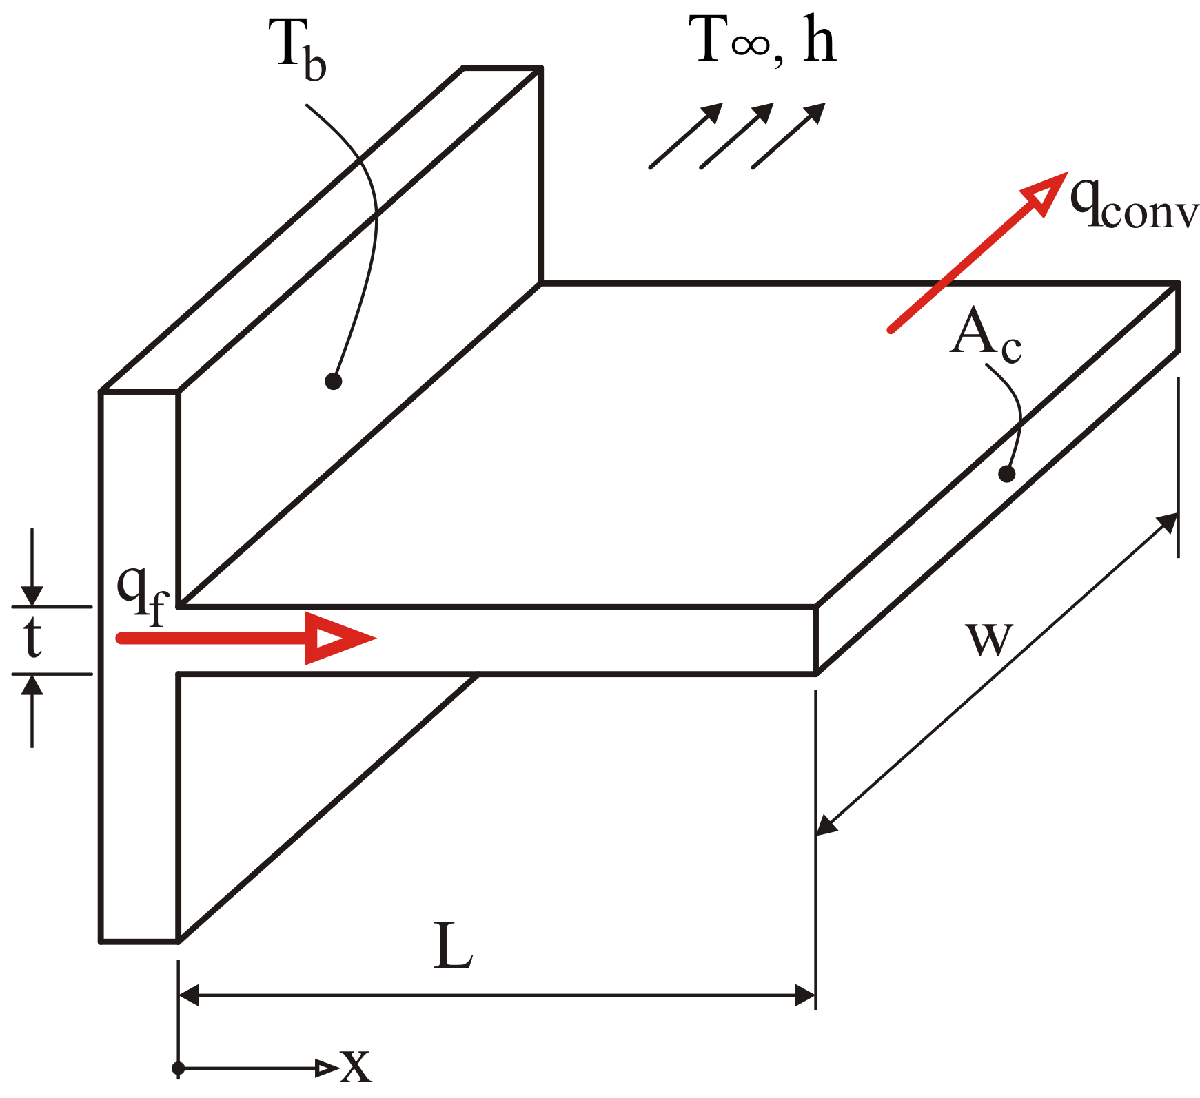

In other cases, one prefers to adopt fins with variable cross-section, e.g. triangular or trapezoidal:

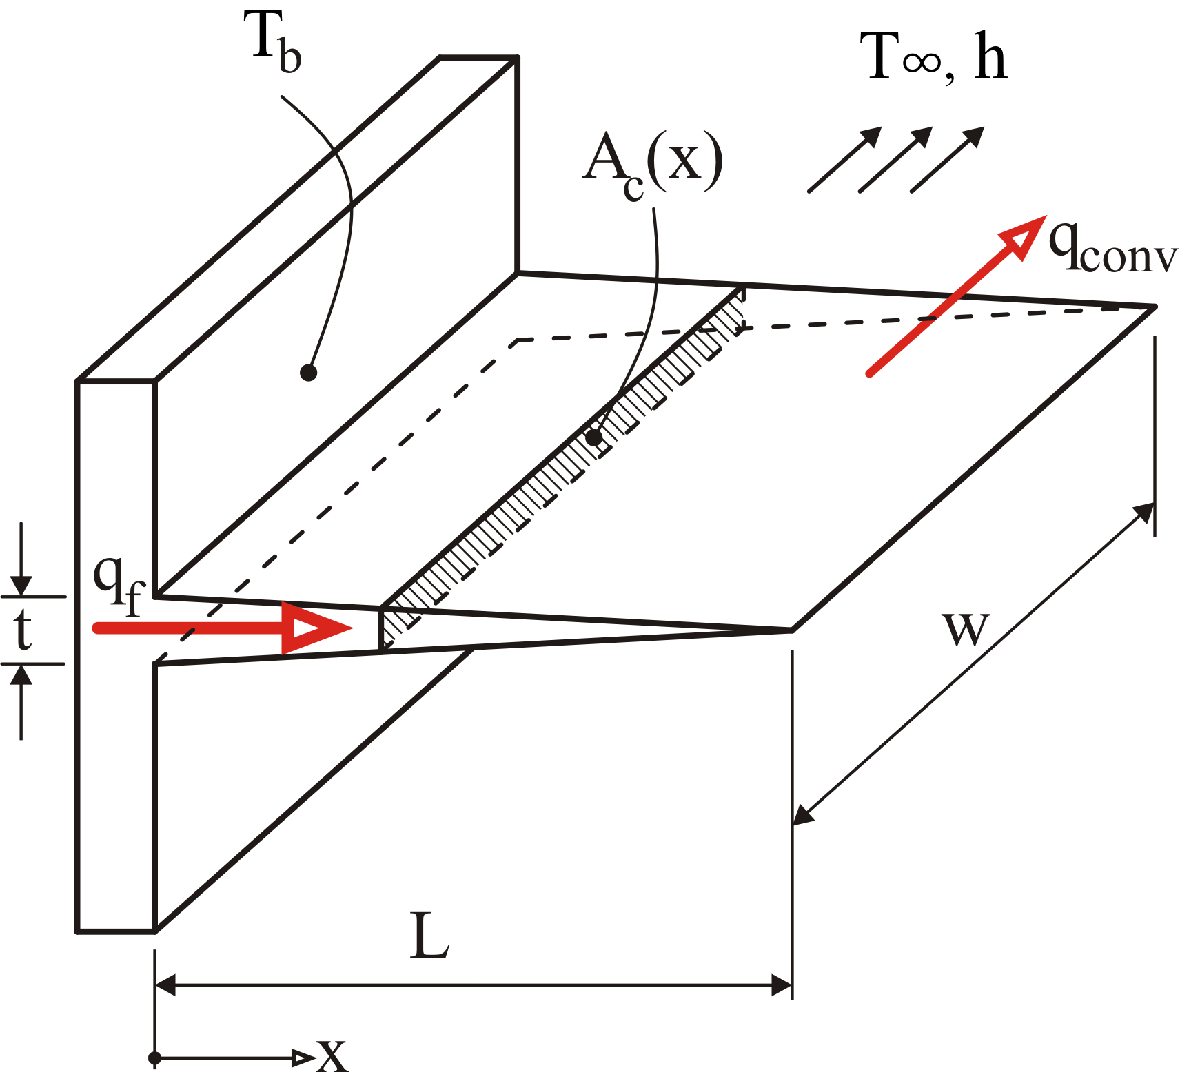       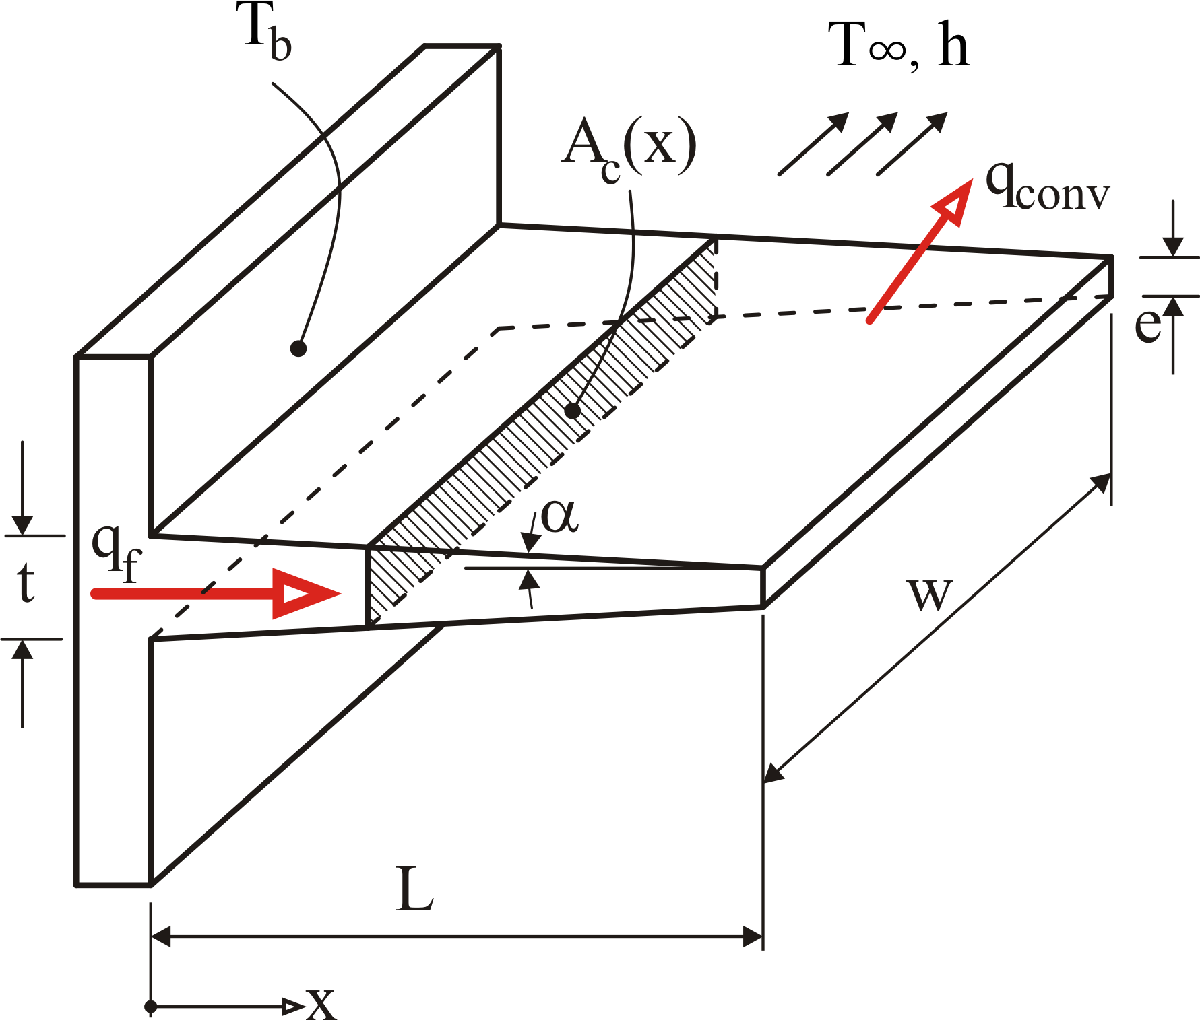

To find out the performances of a fin, it is necessary to determine the temperature distribution within the fin, and for this purpose is common - and convenient where possible - to adopt the following simplifications:

- One-dimensional temperature field, i.e. the temperature varies only along the main axis of the fin.

- Steady state.

- Constant thermal conductivity.

- Negligible heat transfer by radiation.

- No thermal generation within the fin.

- Convective heat transfer coefficient $h$ constant along the entire fin.

The assumption 1. is justified by the small thickness of the fins, which in turn leads to temperature variations, within their cross-section, that are usually negligible in comparison to the temperature difference between the fin and the surroundng fluid. 

With these hypotheses, and assuming that the cross-section $A_{c}$ of the fin is either constant or varies along the $x$ axis with a linear or parabolic profile, it is possible to proceed analytically, by performing an energy balance on a differential element of the fin of length $dx$ [1, 2]. The result is a 2nd order ordinary differential equation (ODE) where the two corresponding constants are obtained from the boundary conditions. This equation could be integrated, in the standard way, for a generic *finite elementary volume,* i.e.a *Finite Volume *$\Delta V_{i}$, of the fin, obtaining an algebraic equation for its temperature $T_{i}$. Repeating this step for all the finite volumes which resulted from the discretization of the fin, will finally leads to a linear system of equations for the unknown temperatures$T_{i}, i = 1,...N$, where $N$ is the total number of finite volumes.

## Analysis with the Finite Volume method

### The algebraic equation for internal volumes

With the Finite Volume method (FVM for brevity), it is possible to avoid the passage from differential $\rightarrow$finite, and apply an energy balance directly to the Finite Volume sketched here:

  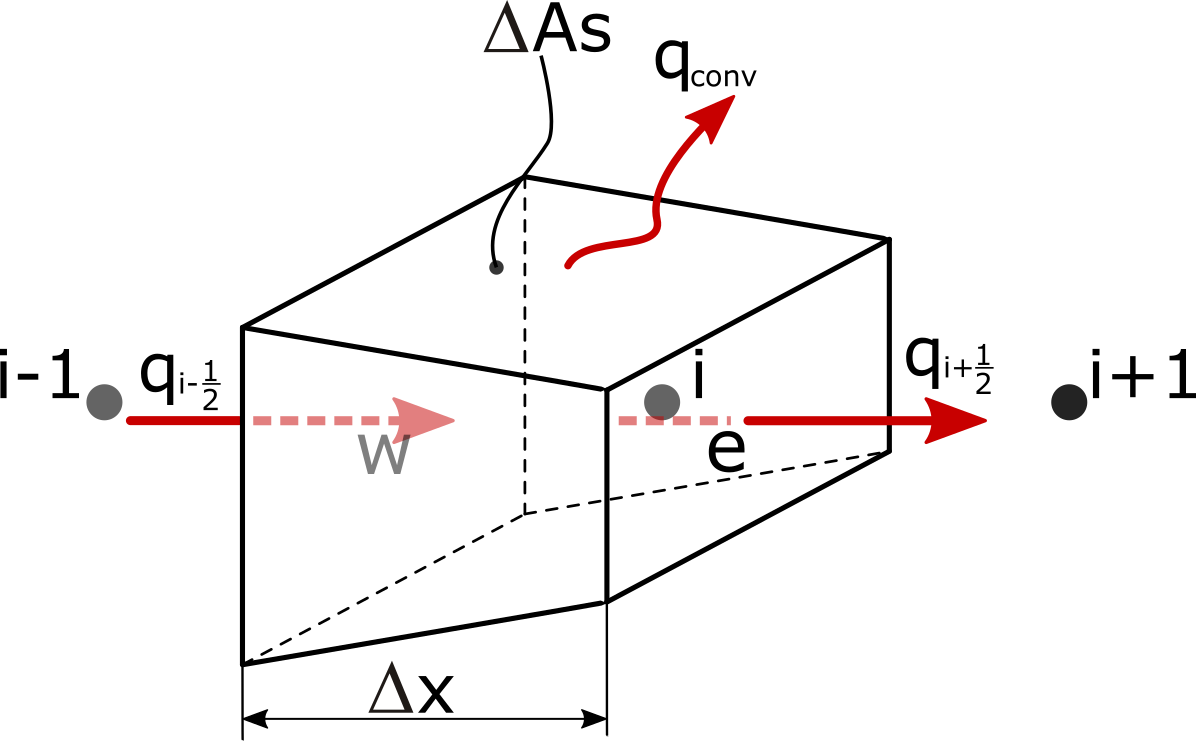


$$q_{i-\frac{1}{2}} -q_{i+\frac{1}{2}} - q_{conv} = 0$$


The advantage is not only conceptual, but also practical, since some of the above simplifications could be abandoned, e.g. we may consider temperature-dependent thermal conductivity, non-uniform convection coefficient, heat transfer by radiation and variable fin cross-section. 

However, for simplicity, we maintain the same simplifications, and therefore the previous energy balance becames


$$- k \,A_{c, i - \frac{1}{2}} \; \left.\frac{dT}{dx} \right|_{ i - \frac{1}{2}} + k \, A_{c, i + \frac{1}{2}}  \; \left.\frac{dT}{dx} \right|_{ i + \frac{1}{2}} - \Delta A_{s,i} h \left(T_{i} - T_{\infty} \right) = 0$$
  

Using the 2nd order Central Difference Scheme (CDS) for the evaluation of the conductive flux, we obtain


$$- k \,A_{c, i - \frac{1}{2}} \frac{T_{i} - T_{i-1}}{\Delta x} + k \, A_{c, i + \frac{1}{2}}  \frac{T_{i+1} - T_{i}}{\Delta x} - \Delta A_{s,i} h \left(T_{i} - T_{\infty} \right) = 0$$
 

This equation, which has to be written for all internal control volumes $i = 2,...N-1$, can be expressed in the usual form


$$A_{W_{i}} \, T_{i-1} + A_{P_{i}}\, T_{i} + A_{E_{i}} \, T_{i+1} = S_{P_{i}}$$


where


$$S_{P_{i}} = - \Delta A_{s,i} \,h \,T_{\infty}$$



$$A_{W_{i}} = k \frac{A_{c,i-\frac{1}{2}}}{\Delta x}$$



$$A_{E_{i}} = k \frac{A_{c,i+\frac{1}{2}}}{\Delta x}$$



$$A_{P_{i}} = - \left(A_{W_{i}}+A_{E_{i}}   \right) - \Delta A_{s,i} \,h$$


### The algebraic equations for the boundary volumes

The energy balance for the first, $i = 1$, and last, $i= N$, volumes, are written accordingly to the boundary conditions.

1. For the first cell, it is assumed that the temperature at the base of the fin, $T_{b}$ is known

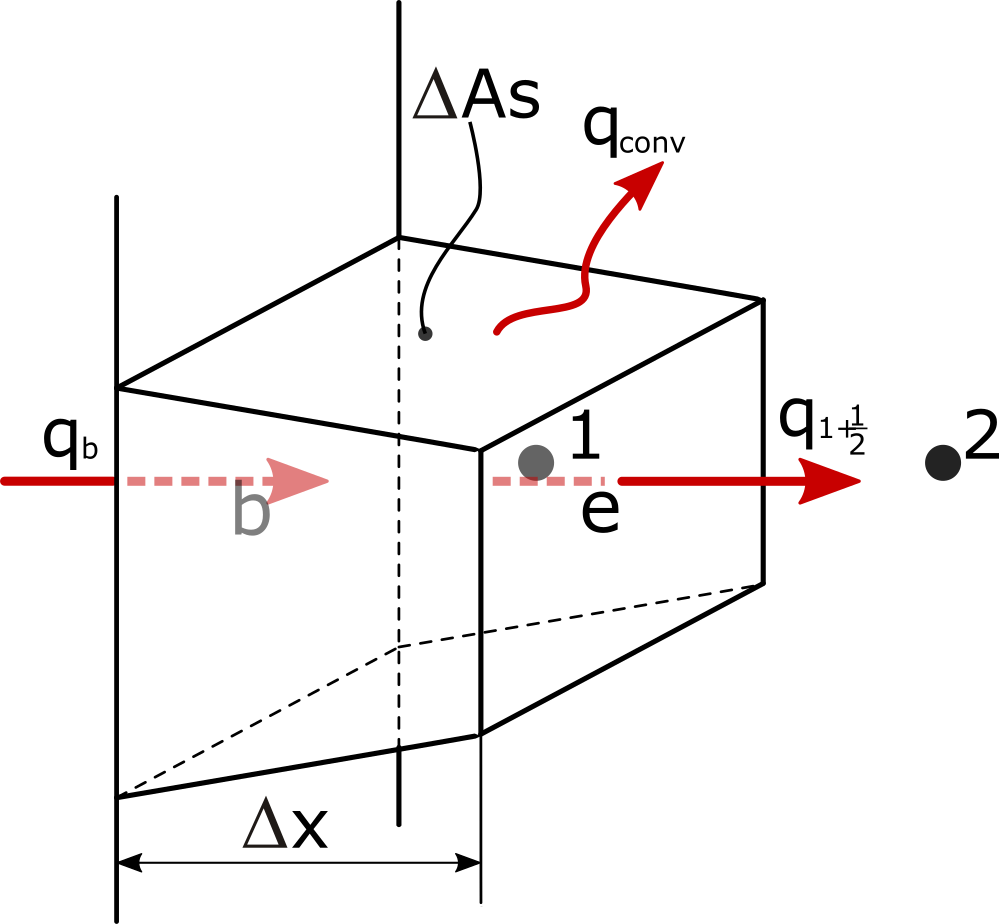

therefore


$$-k \, A_{c,b} \, \left. \frac{dT}{dx} \right|_{b} + k \, A_{c,1+\frac{1}{2}} \left. \frac{dT}{dx} \right|_{1+\frac{1}{2}} - A_{s,1} \, h \left(T_{1} - T_{\infty} \right) = 0$$


by noting that


$$\left. \frac{dT}{dx} \right|_{b} \approx \frac{T_{1}- T_{b}}{\Delta x/2}$$


it follows that the algebraic equation for the first cell is


$$A_{P_{1}}\, T_{1} + A_{E_{1}} \, T_{2} = S_{P_{1}}$$


with


$$S_{P_{1}} = - \Delta A_{s,1} \, h \, T_{\infty} - \frac{2 \,k \, A_{c,b} T_{b}}{\Delta x}$$



$$A_{E_{1}} = \frac{k \, A_{c,1+\frac{1}{2}}}{\Delta x}$$



$$A_{P_{1}} = - A_{E_{1}} - \frac{2 \, k \, A_{c,b}}{\Delta x} - h \, \Delta A_{s,1}$$


2. For the last cell at the tip of the fin, there are typically four types of boundary conditions [1, 2]:

- Adiabatic, $\left. \frac{dT}{dx} \right|_{x=L} = 0$

- Prescribed temperature, $T(L) = T_{L}$

- Infinite fin, $T(L) = T_{\infty}$

- Convection heat transfer, $-k \, \left. \frac{dT}{dx}\right|_{x=L} = h\left(T_{L} - T_{\infty} \right)$

 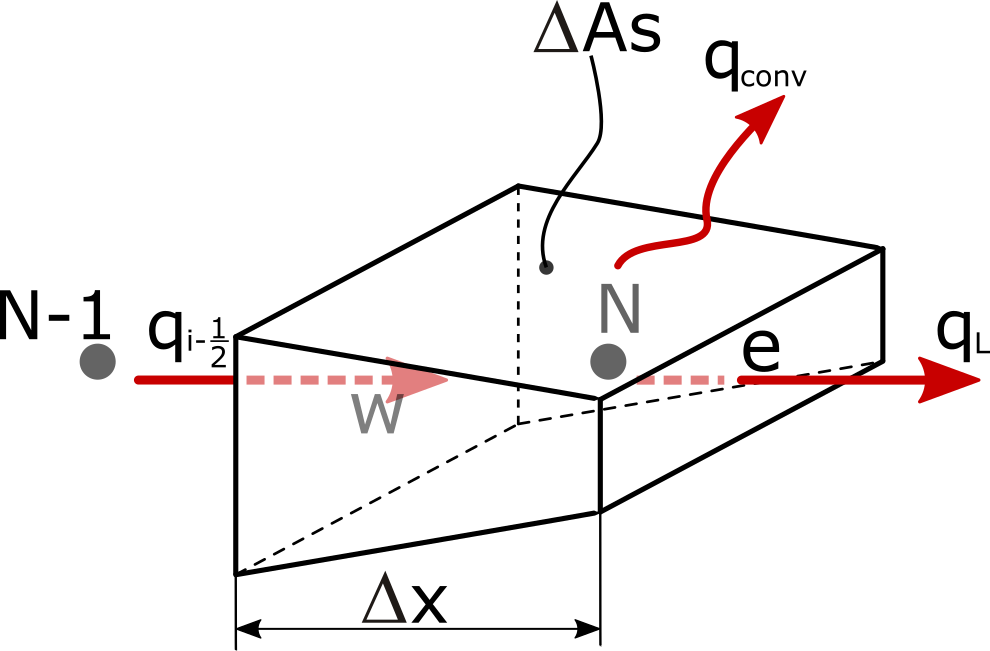

If we assume, for example, condition 4. (convection at the tip), it easy to show that 


$$- k \, A_{c, N-\frac{1}{2}} \left. \frac{dT}{dx} \right|_{N-\frac{1}{2}} + k A_{c,L} \left. \frac{dT}{dx} \right|_{L} - \Delta A_{s,N} \left(T_{N} - T_{\infty} \right) = 0$$


and since


$$- k \, \left. \frac{dT}{dx} \right|_{L}= h \left(T_{N} - T_{\infty} \right)$$


it follows that the algebraic equation for the last cell is


$$A_{W_{N}} T_{N-1} + A_{P_{N}} T_{N} = S_{P_{N}}$$


with


$$S_{P_{N}} = - h \, T_{\infty} \left(A_{c,L} + \Delta A_{s,N} \right)$$



$$A_{W_{N}} = \frac{k \, A_{c,N-\frac{1}{2}}}{\Delta x}$$



$$A_{P_{N}} = - A_{W_{N}} - A_{c,L} \, h - \Delta A_{s,N}\, h$$


## The MATLAB script

Preliminaries:

clear all;
close all;
clc;

Let us consider, as an example, a straight rectangular fin of unit width, with the following data:

% Length of fin [m]
L = 0.2

L = 0.2000

% Thickness of fin [m]
t = 0.02

t = 0.0200

% Convection coefficient [W/m^2 K]
h = 500

h = 500

k = 50;    % Thermal conductivity of fin [W/m K]
Tinf = 25;    % Ambient temperature [°C]
Tb   = 200;   % Fin base temperature [°C]
Ac = t;       % Cross-section of fin of unitary depth (t*1)

We define the number of Finite Volumes, $N$, used to discretize the fin:

N = 10;

We preallocate 1D arrays for the calculations:

AE   = zeros(N,1);  % East coefficient
AW   = zeros(N,1);  % West coefficient
AP   = zeros(N,1);  % Central coefficient
SP   = zeros(N,1);  % Source
T    = zeros(N,1);  % Temperature

Discretize the fin:

Dx        = L/N;                       % Length of each FV
Xf        = linspace(0,L,N+1);         % Position of CV faces
inode     = 1:N;                       % Index of all nodes
Xc(inode) = (Xf(inode)+Xf(inode+1))/2; % Position of CV centroids
DAs       = 2*Dx;                      % External surface for each CV

Set the equation coefficients and source term for all internal FVs:

AE(1:N-1) = (k/Dx)*Ac;
AW(2:N)   = (k/Dx)*Ac;
AP(:)     = -(AW+AE)-DAs*h;
SP(:)     = - DAs*h*Tinf;

#### Boundary conditions

Fixed temperature at the base:

AP(1)     = AP(1)-(2*k/Dx)*Ac;
SP(1)     = SP(1)-(2*k/Dx)*Ac*Tb;

Convection at the tip:

AP(N)     = AP(N)-h*Ac;
SP(N)     = SP(N)-h*Tinf*Ac;

Assemble sparse tridiagonal matrix:

A = spdiags([circshift(AW,[-1 0]) AP circshift(AE,[1 0])],...
    [-1 0 1], N, N);

We can visualize the matrix A:

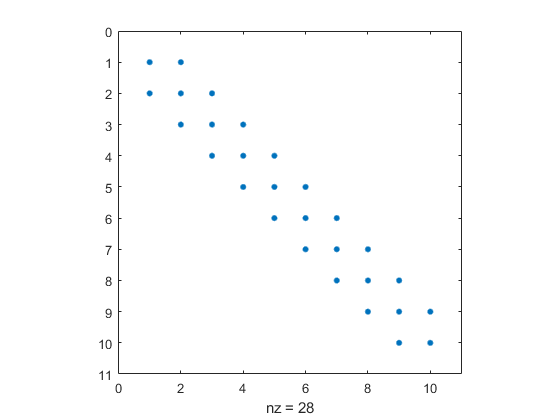

spy(A);

Solve the tridiagonal system:

T = A\SP;

We may visualize also the temperature profile along the fin:

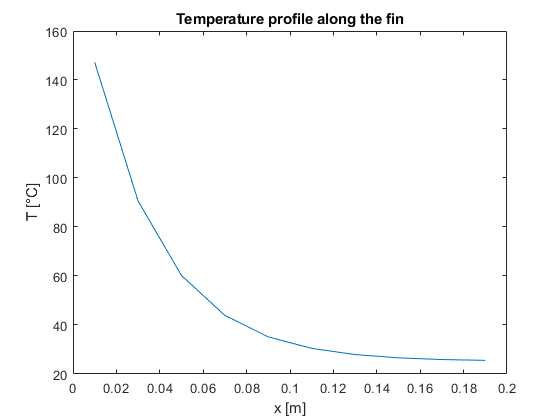

plot(Xc,T);
hold on;
xlabel('x [m]');
ylabel('T [°C]');
title('Temperature profile along the fin');

In order to calculate the overall heat flux from the fin to the ambient, there are two possibilities.

a) Compute the conductive flux at the base of the fin:


$$q_{f} = q_{b} = - k \, A_{c,b} \left. \frac{dT}{dx} \right|_{x=0} = -k \, A_{c,b} \frac{T_{1} - T_{b}}{\Delta x/2}$$


b) Compute the overall convective heat flux from the fin:


$$q_{f} = \int_{A_{s}} h \,\left(T_{x} - T_{\infty}   \right) dA_{s} = \sum_{i=1}^{N}h \, \left(T_{i}-T_{\infty}\right) \Delta A_{s}$$


We select the first approach, since it is more economical to compute (with the Finite Volume method, both approaches lead to exactly the same result, no matter the value of $N$):

qfNum = -2*k*Ac*(T(1)-Tb)/Dx;
disp(['Computed heat flux = ', num2str(qfNum),' [W/m]']);

Computed heat flux = 5276.4294 [W/m]


Finally, we can compare this result with the *exact value*, obtained from the following analytical relation [1, 2]:


$$q_{f} = M\, \frac{\sinh mL +(h/mk) \cosh mL}{\cosh mL + (h/mk \sinh mL}$$


con

$m = \sqrt{hP/k A_{c}}$   and    $M = \sqrt{hPkA_{c}} \left(T_{b}-T_{\infty}\right)$

where $P$ is the perimeter of the fin, which in our case is equal to $2$ (unitary width).

P = 2;
m = sqrt((h*P)/(k*Ac));
M = sqrt(h*P*k*Ac)*(Tb-Tinf);
qfTeor = M * (sinh(m*L)+(h/(m*k))*cosh(m*L))/...
    (cosh(m*L)+(h/(m*k))*sinh(m*L));
disp(['Theoretical heat flux = ', num2str(qfTeor),' [W/m]']);

Theoretical heat flux = 5533.9674 [W/m]


The % difference is:

diff = (abs(qfNum-qfTeor))/qfTeor*100;
disp(['Difference Num.-Analyt. = ', num2str(diff),' %']);

Difference Num.-Analyt. = 4.6538 %


It is easy now to:

- Verify that the difference decreases quadratically with $N$, i.e. the method is second-order accurate

- Modify the script to consider other fin shapes, e.g. triangular, trapezoidal et.

- Consider temperature-dependent thermophysical properties

- Evaluate the contribution of heat transfer by radiation

- etc.

### References

[1] F. P. Incropera, D. P. Dewitt, T. L. Bergman, A. S. Lavine, *Fundamentals of Heat and Mass Transfer*, 6th Ed., Wiley, (2007).

[2] A. J. Chapman, *Heat Transfer*, 4th Ed., Macmillan Publ. Comp., (1984).